# Analyze Daily Temperatures in Natick

Here at MathWorks, we have a weather station on top of one of our buildings.  It collects data on wind speed, temperature, humidity, atmospheric pressure, and rain fall.  

## Get Data from ThingSpeak Weather Station

We can retrieve the weather data from ThingSpeak, MathWorks IoT analytics platform, using the `thingSpeakRead` function.  We can set the date using the sliders below.

year = 2019;   
month = 7 ;
day = 24;    

d1 = datetime(year, month, day, 0, 0, 0);
if d1 > datetime(datestr(today))
    d1 = datetime(datestr(today));
end
d2 = d1 + days(1);

chID = 12397;
weatherData = thingSpeakRead(chID, "Fields", 1:8, "DateRange",[d1, d2], "outputFormat", "TimeTable")

weatherData = 1407×8 timetable
         Timestamps         WindDirectionNorth0Degrees    WindSpeedmph    Humidity    TemperatureF    RainInchesminute    PressureHg    PowerLevelV    LightIntensity
    ____________________    __________________________    ____________    ________    ____________    ________________    __________    ___________    ______________
    24-Jul-2019 00:00:02                0                     1.6            65           72.6               0               29.7           3.4              52      
    24-Jul-2019 00:01:05                0                     1.4            65           72.6               0               29.7  

if isempty(weatherData)
    error("No data available for " + datestr(d1,"yyyy-MMM-dd"))
end

## Visualize the Data

Now let"s visualize the data coming back from the weather station.

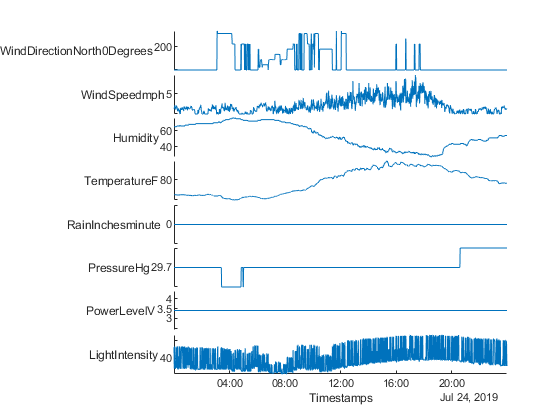

stackedplot(weatherData);

## **Smooth Temperature Data**

We want to calculate the temperature extremes for a certain day but we know there is a certain amount of noise in the reported data.  We can use the ***Smooth Data*** Live Editor Task to clean up the temperature data a bit.

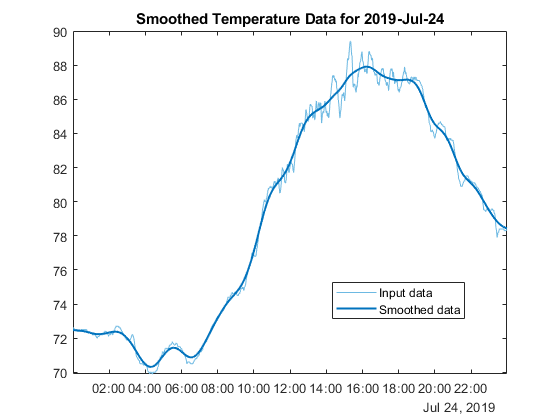

% Smooth input data
smoothedTemp = smoothdata(weatherData.TemperatureF,...
    'gaussian','SmoothingFactor',0.02,'SamplePoints',weatherData.Timestamps);

% Visualize results
clf
plot(weatherData.Timestamps,weatherData.TemperatureF,...
    'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(weatherData.Timestamps,smoothedTemp,'Color',[0 114 189]/255,...
    'LineWidth',1.5,'DisplayName','Smoothed data')
hold off
legend
xlim(weatherData.Timestamps([1, end]))
title("Smoothed Temperature Data for " + datestr(d1,"yyyy-mmm-dd"))
legend("Location","best")

## Calculate Daily Temperature Extrema

Now we can find the local minima and maxima in the data using the ***Find Local Extrema*** Live Editor Task

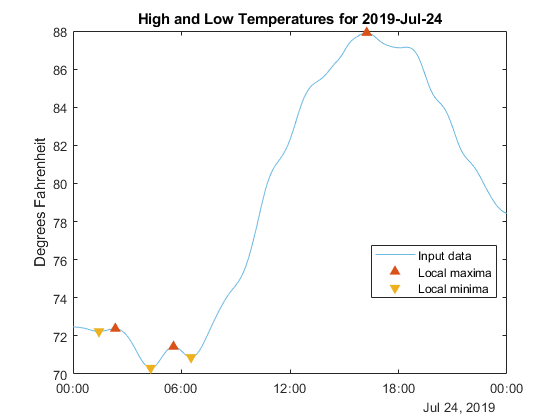

% Find local maxima and minima
maxIndices = islocalmax(smoothedTemp,'MinProminence',0.1,...
    'ProminenceWindow',hours(2),'FlatSelection','last','MinSeparation',hours(2),...
    'MaxNumExtrema',8,'SamplePoints',weatherData.Timestamps);
minIndices = islocalmin(smoothedTemp,'MinProminence',0.1,...
    'ProminenceWindow',hours(2),'FlatSelection','last','MinSeparation',hours(2),...
    'MaxNumExtrema',8,'SamplePoints',weatherData.Timestamps);

% Visualize results
clf
plot(weatherData.Timestamps,smoothedTemp,'Color',[109 185 226]/255,...
    'DisplayName','Input data')
hold on

% Plot local maxima
plot(weatherData.Timestamps(maxIndices),smoothedTemp(maxIndices),'^',...
    'Color',[217 83 25]/255,'MarkerFaceColor',[217 83 25]/255,...
    'DisplayName','Local maxima')

% Plot local minima
plot(weatherData.Timestamps(minIndices),smoothedTemp(minIndices),'v',...
    'Color',[237 177 32]/255,'MarkerFaceColor',[237 177 32]/255,...
    'DisplayName','Local minima')
title(['Number of extrema: ' num2str(nnz(maxIndices)+nnz(minIndices))])
hold off
legend
legend("Location","best")
title("High and Low Temperatures for " + datestr(d1,"yyyy-mmm-dd"))
ylabel("Degrees Fahrenheit")

## Calculate the Minimum and Maximum Temperatures and the Largest Change for the Day

We can now complete our analysis by calculating the maximum, minimum, and largest temperature change over the course of the day.

minTemp = min(smoothedTemp);
maxTemp = max(smoothedTemp);
tempChanges = diff(smoothedTemp(maxIndices | minIndices));
[~,idx] = max(abs(tempChanges));
maxChange = tempChanges(idx);

str = sprintf("Maximum Temperature = %4.1f degF\n", maxTemp);
str = [str sprintf("Minimum Temperature = %4.1f degF\n",minTemp)];
str = [str sprintf("Largest Change      = %4.1f degF\n",maxChange)];
fprintf("%s",str)

Maximum Temperature = 87.9 degF
Minimum Temperature = 70.3 degF
Largest Change      = 17.0 degF


*Copyright 2019 The MathWorks, Inc.*